# First script

The equation we want to solve is the following:


$$\frac{\partial a}{\partial z}=-\beta_1\frac{\partial a}{\partial t}-i\frac{\beta_2}{2}\frac{\partial^2 a}{\partial t^2}-\frac{\alpha}{2}a$$


It is integrated using the beam propagation method: the solution in fourier domain is given and it is the exponetial:


$$\tilde{a}(z,\Omega)=a(0,\Omega)e^{i Pz }$$


Where $P$ is the propagator of the problem and it is 


$$\beta_1\Omega+\frac{1}{2}\beta_2\Omega^2+\frac{i\alpha}{2}$$


We can take small step in z, $\Delta z
$ and the solution will be:


$$a(z+\Delta z,T)=\int d\Omega\ \tilde{a}(z+\Delta z,\Omega) e^{-i\Omega T}$$


## Setting parameters

T=500e-15;              %T_max dell'intervallo campionato in s
T0=80e-15;              %durata dell'impulso in s
s0=T0/2.355*sqrt(2);    %conversion FWHM to sigma
tp0=0;                  %posizione iniziale dell'impulso in s
beta1=0/(3e8/1.52);   
% zmax=50e-6;           %distanza massima all'interno del materiale dispersivo
beta2=1*2e-26;          %beta_2 for optical fiber
% beta2=0*7.6e-26;      %beta_2 for optical silica
% beta2=1*5.3e-26;      %beta_2 for CaF2
zmax=0.15;              %distanza massima all'interno del materiale dispersivo 
% alpha=1*1/22000;    
alpha=0*2;              % esagerated absortpion
C=1*-2;%-2;             %initial chirp 

SaveVideo=0;            % controllo per salvare un video
Ld=s0*s0/abs(beta2);    %lunghezza di dispersione
N=1024*8;               % numero di tempi campionati
nsteps=30;              % numero di passi per la propagazione in z
dz=zmax/nsteps;

## Fourier replicas

We create a vector with all the time where the pulse is defined and, according to Nyquist theorem of sampling, we divide the frequency domain.

t=linspace(-T,T,N);     % creo il vettore dei tempi

f=zeros(size(t));       % creo vettore delle frequenze nullo da riempire
dF=1/(2*T);
for i=1:N/2
    f(i)=(i-1)*dF;
    f(N/2+i)=-(N/2-i+1)*dF;
end

## Parameter for the propagation

We define the propagator and the pulse at the beginning. See that you can define new types of pulses 

Omega=2*pi*f;
Dbeta=beta1*Omega+0.5*beta2*Omega.^2+1i*alpha*0.5;
propagator=exp(1i*Dbeta*dz);
all_intensities=zeros(N,nsteps+1);
zplot=zeros(1,nsteps+1);

A=exp(-(1+1i*C).*((t-tp0).^2/(2*s0^2)));
%figure,plot(t,real(A.*exp(-1i*1e14.*t)))
% A=1.*exp(-(1+1i*C).*(abs(t-tp0)/(2*s0)));
% A=sech(t/T0).*exp(-1i*C*(t-tp0).^2/(2*T0^2));
% w=T0; %width of rectangle
% A=rectpuls(t,2*w);
all_intensities(1:N,1)=abs(A).^2;

## Propagation

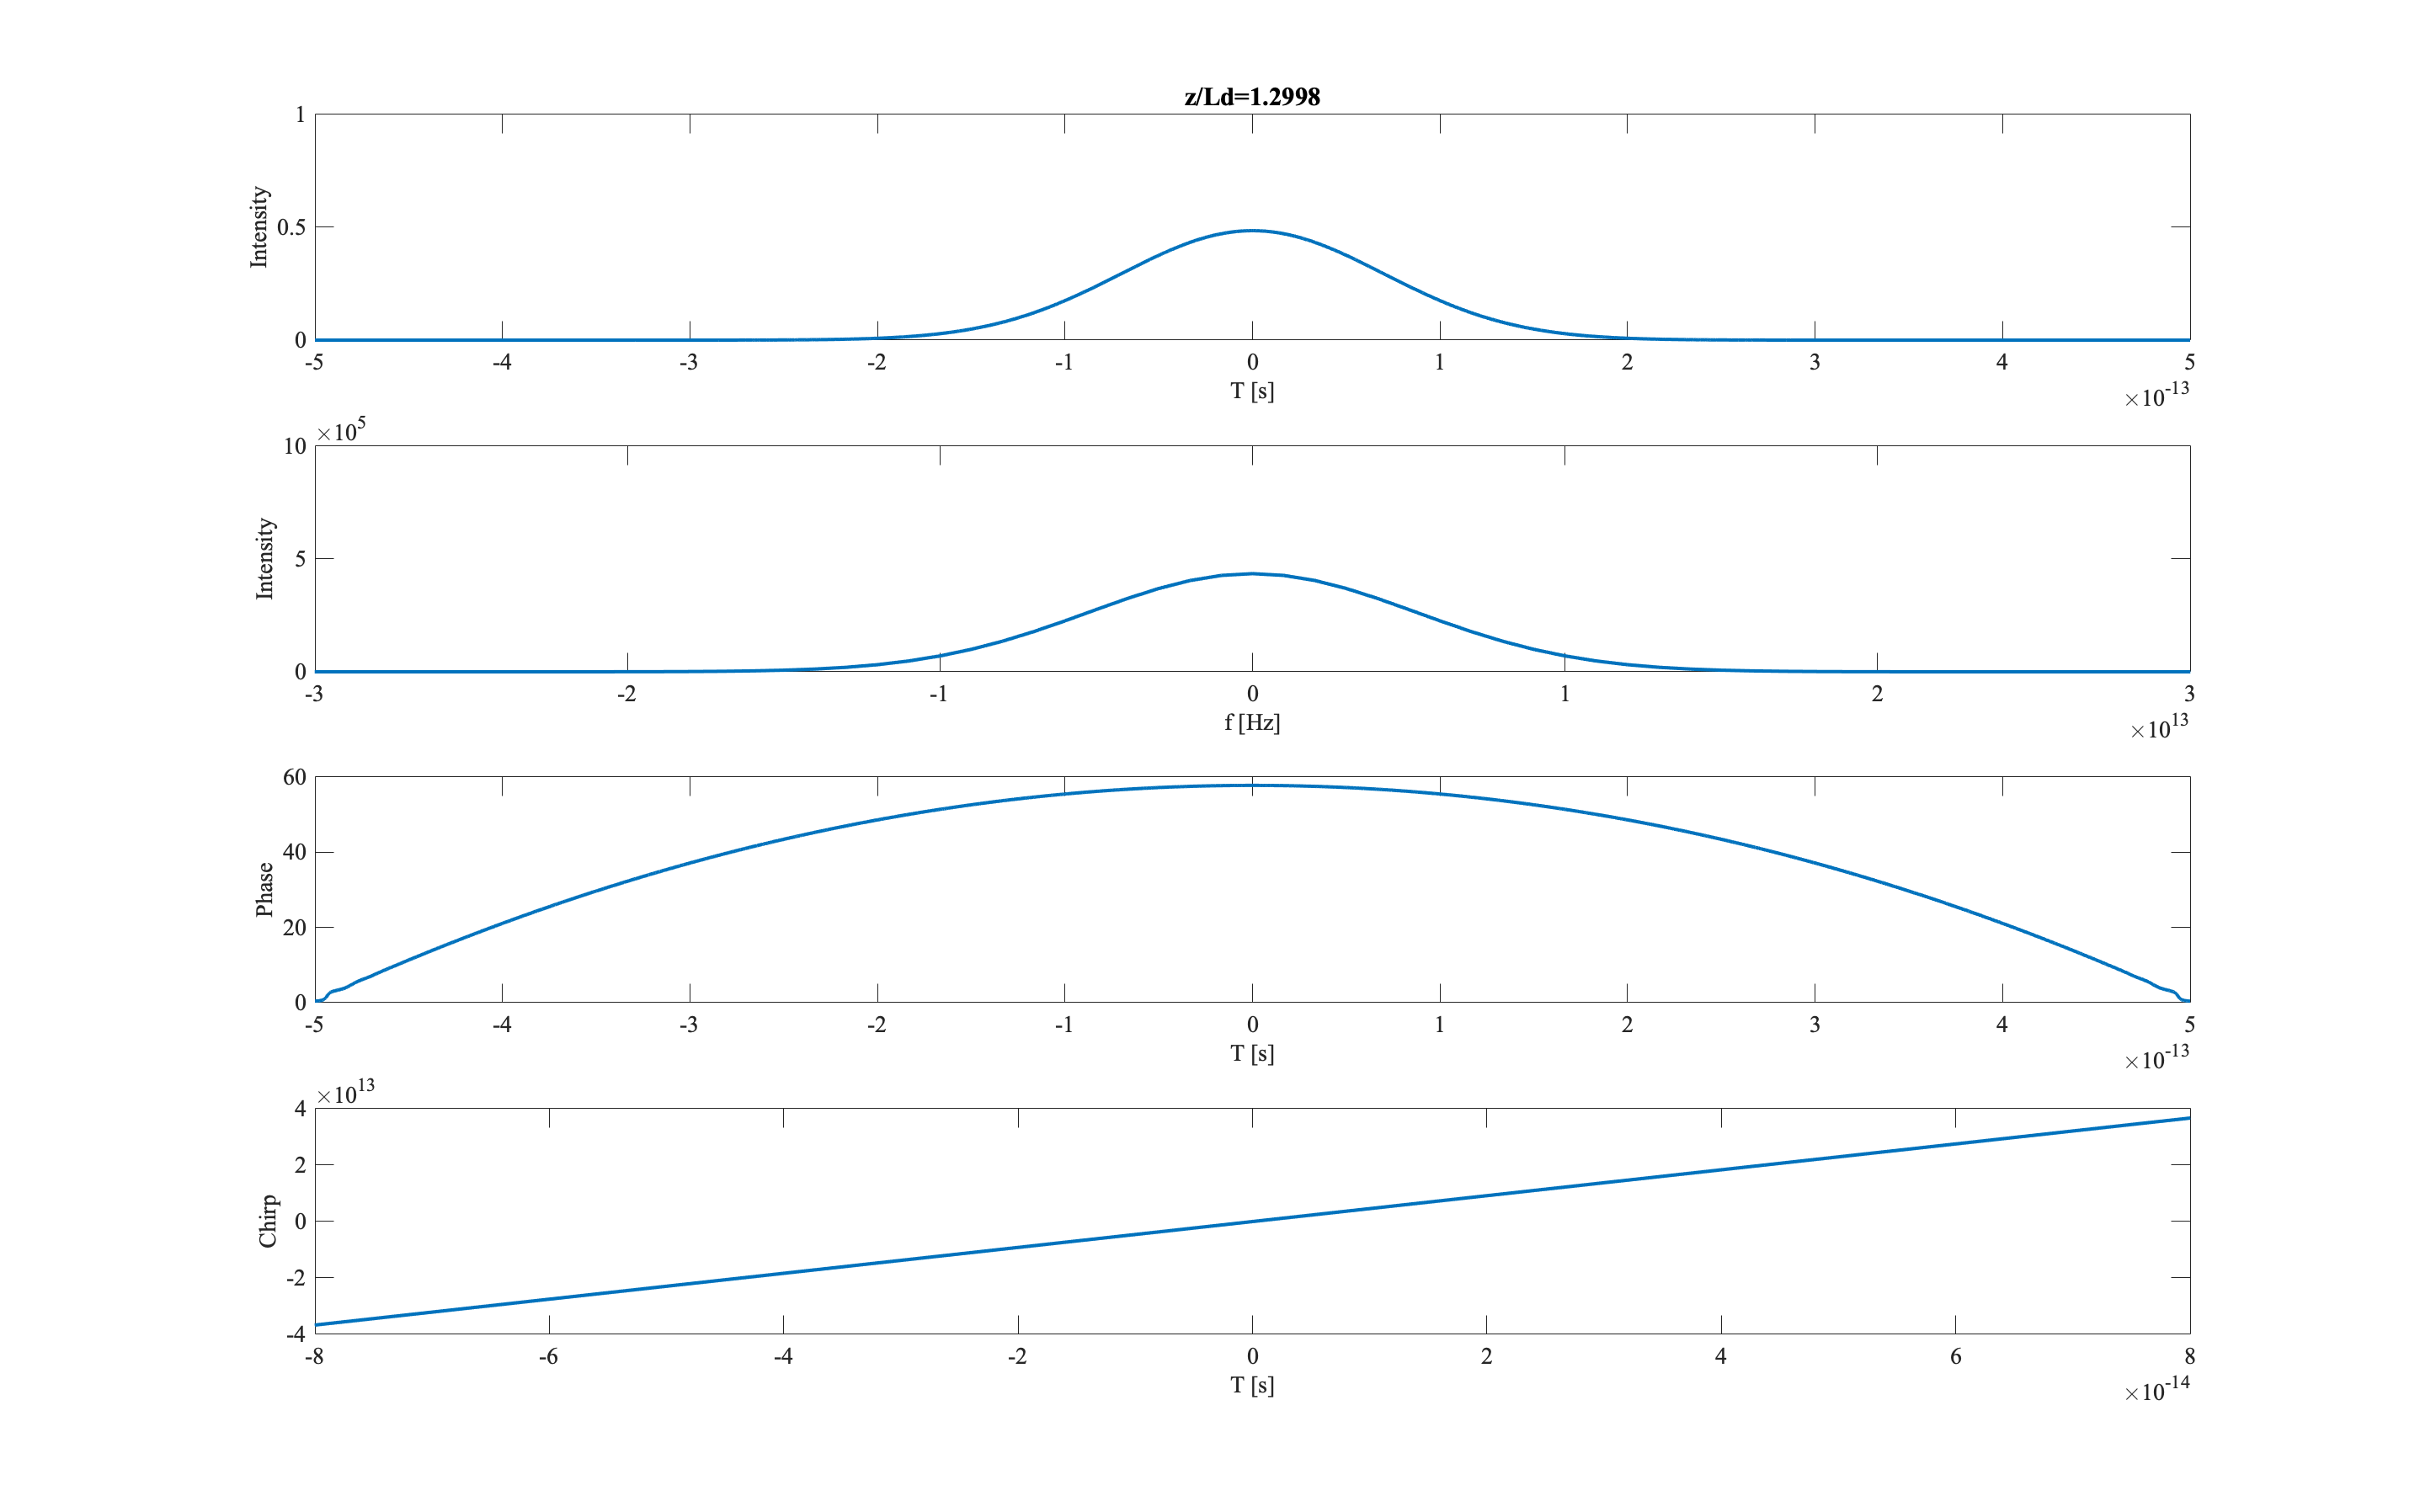

figure(1)
set(gcf,'units','normalized','outerposition',[0 0 1 1]);

if SaveVideo
    aviobj2=VideoWriter('Video_Dispersion2.avi');
    aviobj2.FrameRate =10;
    open(aviobj2)
end

sigma0=sqrt(sum(t.^2.*abs(A).^2)/sum(abs(A).^2)...
    -(sum(t.*abs(A).^2)/sum(abs(A).^2))^2);
Broadening(1)=1;

for iz=1:nsteps
    A=ifft(fft(A).*propagator);
    fase=unwrap(angle(A));
    chirp=-ifft(fft(fase).*1i.*Omega);

        
    
    
    figure(1)
    subplot(4,1,1)
    plot(t,abs(A).^2);
    xlabel('T [s]')
    ylabel('Intensity')
    ylim([0,1])
    
    %title(dz*iz)
    title(['z/Ld=' num2str(dz*iz/Ld) ])
    %title(dz*iz/Ld)
    subplot(4,1,2)
    [n_sortf m_sortf]=sort(f);
    B=fft(A);
    plot(f(m_sortf),abs(B(m_sortf)).^2);
    xlabel('f [Hz]')
    ylabel('Intensity')
    xlim([-3e13,3e13])
    ylim([0,1e6])
    subplot(4,1,3)
    plot(t,fase);
    
    xlabel('T [s]')
    ylabel('Phase')
    subplot(4,1,4)
    plot(t,real(chirp));
    xlabel('T [s]')
    ylabel('Chirp')
    
    xlim([-T0, T0])
    set(findall(gcf,'-property','FontSize'),'FontName',...
        'Times New Roman','FontSize',14)
    set(findobj(gcf,'type','line'),'LineWidth',2)
    pause(.1)
    drawnow
    sigmas=sqrt(sum(t.^2.*abs(A).^2)/sum(abs(A).^2)...
        -(sum(t.*abs(A).^2)/sum(abs(A).^2))^2);
    
    if SaveVideo
        F=getframe(gcf);
        writeVideo(aviobj2,F);
    end
    
    %   pause
    x=dz*iz;
    if abs(beta2)>0
        Broadening(iz+1)=sigmas/sigma0;
    end
    all_intensities(:,iz+1)=abs(A).^2;
    zplot(iz+1)=zplot(iz)+dz;
    %     text(1100,1000,['t=' num2str(x_position(i)) ' ps'])
    
    
end

% close(fig);
if SaveVideo
    close(aviobj2)
end

## New plots

### First : Broadening during propagation

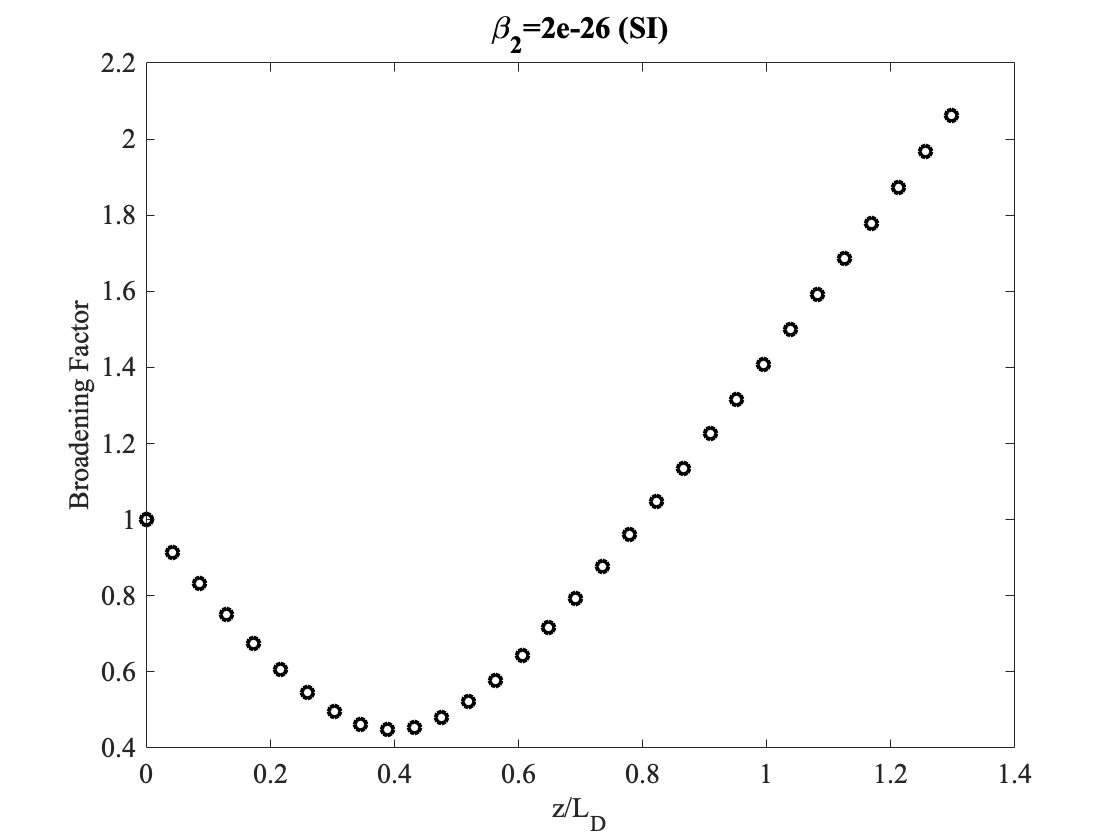

if abs(beta2)>0
    figure(2)
    title ('Broadening Factor')
    plot(zplot/Ld,Broadening, 'ko')
    xlabel('z/L_D')
    title (['\beta_2=', num2str(beta2) ' (SI)'])
    ylabel('Broadening Factor')
    set(findall(gcf,'-property','FontSize'),'FontName',...
        'Times New Roman','FontSize',14)
    set(findobj(gcf,'type','line'),'LineWidth',2)
end

### Second: 3D shape during propagation

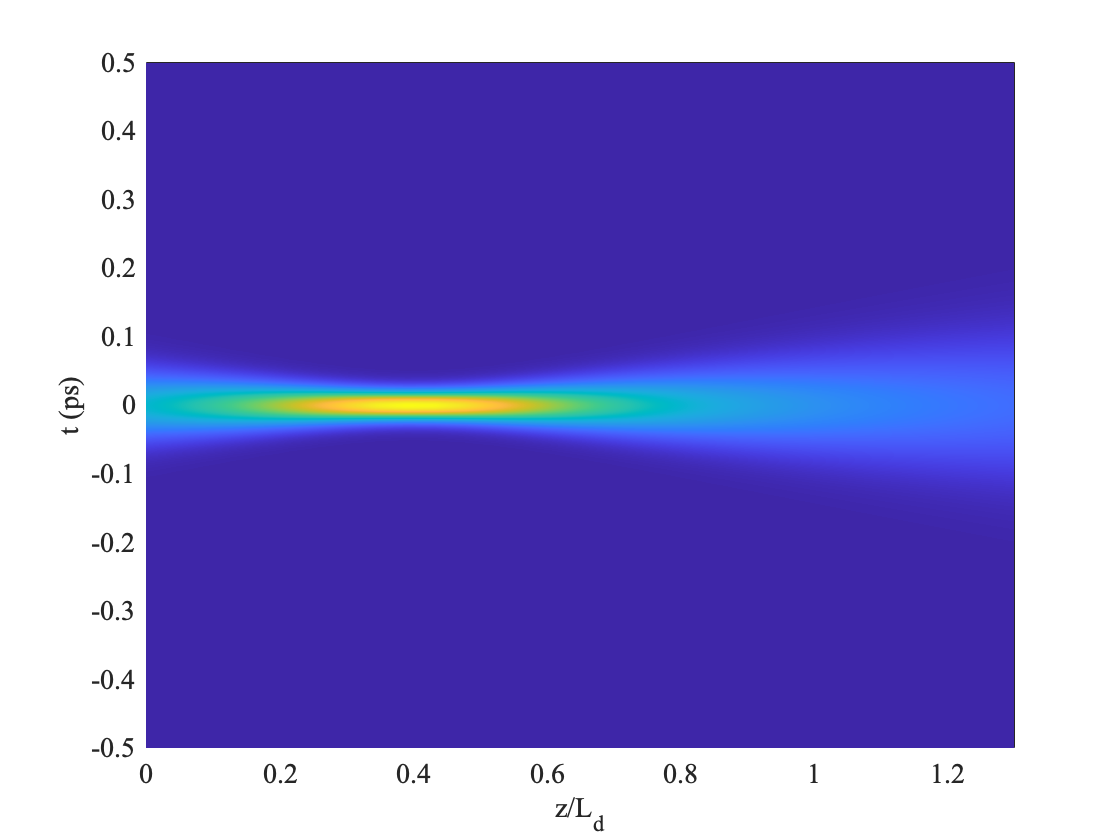

z=zplot./Ld;
figure(3)
if beta2>0
    pcolor(z, t*1e12, all_intensities)
    xlabel('z/L_d')
else
    pcolor(zplot, t*1e12, all_intensities)
    xlabel('z/L_d')
end
shading interp
ylabel('t (ps)')
box on
set(findall(gcf,'-property','FontSize'),'FontName',...
    'Times New Roman','FontSize',14)

set(findobj(gcf,'type','line'),'LineWidth',2)

### Third: shape in 2D and palette for propagation

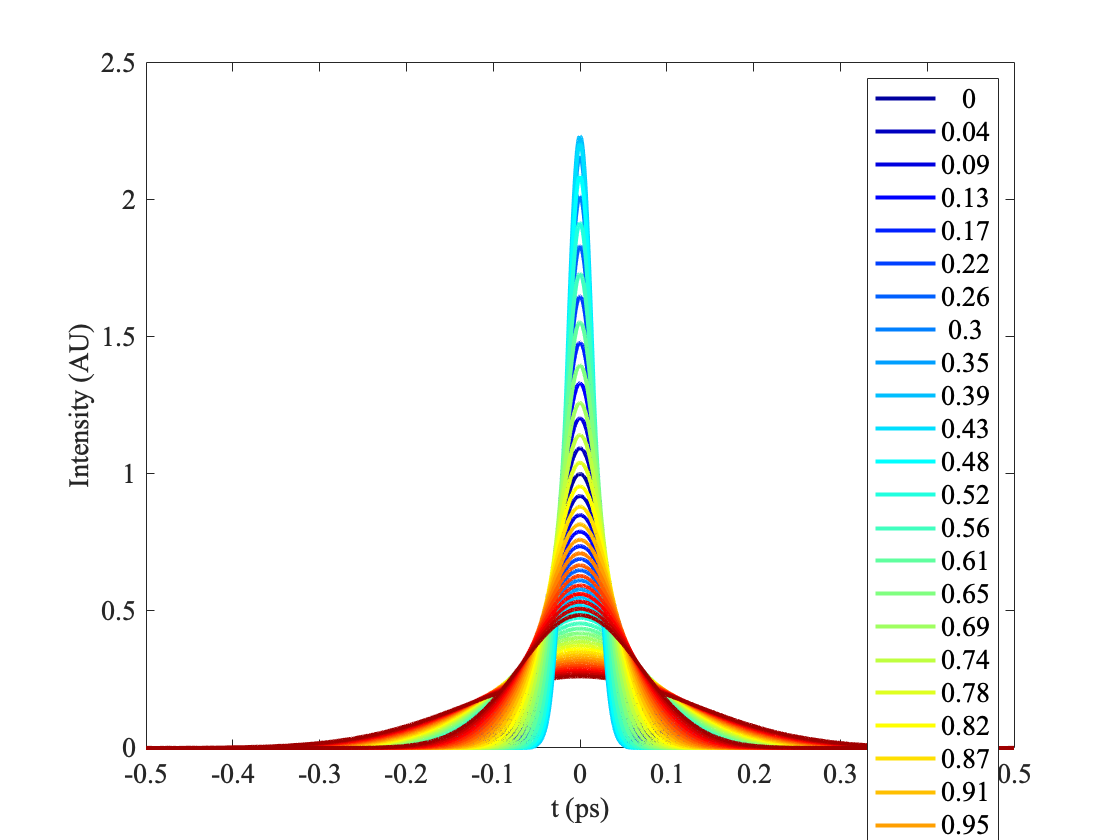

Col=jet(length(zplot));
figure(4),hold on
for k=1:length(zplot)
    plot(t*1e12, all_intensities(:,k),'linewidth',2,'color',Col(k,:))
end
xlabel('t (ps)')
ylabel('Intensity (AU)')
legend(num2str(round(z'*1e2)/1e2))
box on
set(findall(gcf,'-property','FontSize'),'FontName',...
    'Times New Roman','FontSize',14)

set(findobj(gcf,'type','line'),'LineWidth',2)